# Procedure 1 for Closed Koopman System

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5) 
set(0,'defaultfigurecolor',[1 1 1])

## Dynamics

## 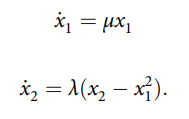

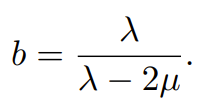

mu=0.5; 
lambda =-10;
f = @(t, x)[mu*x(1,:);  lambda*(x(2,:)-x(1,:).^2)];

## Linearization

n=2; % dimension
x = sym('x',[n;1]);
x0 = [0;0];

A = double(subs(jacobian(f(0,x),x),x,x0)); 
B = [1; 1];
%linear eigenfunctions realization from complex eigenfunctions
[~,D1,W1] = eig(A);
[W, D] = cdf2rdf(W1, D1);

## Selet basis functions to approximate h(x)

x1 = sym('x',[n,1]);
order = 2; %order poly

[Psi, DPsi] = monomial_basis(order, n);

$$Psi = \left(\begin{array}{c} x_{1}\\ x_{2}\\ {x_{2}}^{2}\\ x_{1}\,x_{2}\\ {x_{1}}^{2} \end{array}\right)$$

% Dom = [-20 20]; %Domain
% grid = linspace(Dom(1), Dom(2), 100);
% C = [grid; grid];
%[Psi, DPsi] = GaussianRBF_basis(C, n, 1);
Psi = Psi(n+1:end); %remove linear part
Nbs = length(Psi);
DPsi = jacobian(Psi,x1);

Psi = matlabFunction(Psi,'Vars',{x1});
DPsi = matlabFunction(DPsi,'Vars',{x1});

## Parameters setup

Dom = [-5 5]; %Domain
domain = Dom(2)-Dom(1);

## Collect random initial conditions

numICs = 1e4; %initial coditions
X = rand(n,numICs)*2*Dom(2) - Dom(2); %sample initial conditions

## Try some initial conditions and collect X along trajectories 

Skip this if you run the previous section and generated random initial condtions. (It doesnt make a big difference)

% numICs = 1000;
% tSpan = 0:0.02:1;
% seed = 1; rng(seed)
% 
% lenT = length(tSpan);
% 
% X = zeros(lenT, n);
% 
% count = 1;
% for j = 1:100*numICs
%     % randomly start from x1range(1) to x1range(2)
%     x1 = (domain)*rand+Dom(1);
%     x2 = (domain)*rand+Dom(1);
% 
%     ic = [x1; x2];
%     [T, temp] = ode45(@(t,x)f(t, x), tSpan, ic);
%     X(1+(count-1)*lenT : lenT + (count-1)*lenT,:) = temp;
%     if count == numICs
%         break
%     end
%     count = count + 1;
% end
% X=X';

## Solve the least squares problem to estimate U

E = A;
Ez = E*X;
G_z = Psi(X);
F_z = f(0, X);
Df_z = zeros(Nbs,1);
for i=1:size(X,2)
Df_z(:,i) = DPsi(X(:,i))*f(0, X(:,i));
end

% YALMIP 
U = sdpvar(n,Nbs);
Objective =  norm(U*Df_z + F_z - A*U*G_z - Ez, 'fro'); 
Constraints = [];
opt = sdpsettings('solver','gurobi','verbose',2,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

Set parameter Username
Academic license - for non-commercial use only - expires 2023-02-11
Gurobi Optimizer version 9.5.0 build v9.5.0rc5 (win64)
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 20001 rows, 20008 columns and 80002 nonzeros
Model fingerprint: 0x36c3d0a8
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [3e-08, 3e+03]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [6e-07, 2e+02]
Presolve removed 1 rows and 1 columns
Presolve time: 0.07s
Presolved: 20000 rows, 20007 columns, 80000 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.01s

Barrier statistics:
 Dense cols : 7
 Free vars  : 6
 AA' NZ     : 8.000e+04
 Factor NZ  : 1.000e+05 (roughly 17 MB of memory)
 Factor Ops : 5.001e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       Prim

U = value(U)

U =          0         0         0
    0.0000   -0.0000   -0.9091


## Eigenfunctions of the original system

% nonlinear eigenfuncitons with scaling
Phi = @(x) W'*x + W'*U*Psi(x);
DPhi = @(x) W' + W'*U*DPsi(x);

## Sanity Check for principle eignefunctions

x_eval = [1.2;-1.3];
b = lambda/(2*mu-lambda)

b = -0.9091

## Evaluating analytical eigenfuction

Phi_analytical = @(x)[x(1); x(2)+b*x(1)^2];
Phi_analytical(x_eval)

ans =     1.2000
   -2.6091


## Evaluating eigenfuction approximated from data

Phi(x_eval)

ans =    -2.6091
    1.2000


Note: The order of eigenfunctions does not matter since its its accounted for by the orde of eigenvalues

## LQR controller

Q = 1*eye(2,2); %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A,B,Q,R_lqr);
uLQR = @(x) -K*(x);

## HJ-Koopman Controller:

Where,

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

R_Koopman = B*inv(R_lqr)*B';
hat_R = W'*(R_Koopman)*W;
W1_inv = inv(W);
hat_Q = W1_inv*Q*W1_inv';
L = care(D,hat_R,hat_Q);
L1 = W*L*W';

uKoop=@(x) -Phi(x)'*L*DPhi(x)*B;

## Sanity Check for linear basis

## P should match with L1

P

P =     1.6286   -0.0073
   -0.0073    0.0499


L1 

L1 =     1.0116   -0.0087
   -0.0087    0.0498


## Simulation

(change x_initial to simulate response of different initial conditions and plot)

For Q=I and R_lqr = 1, when the initial conditions are very far from 0 like (10,10), HKJ doesnt stabilize

Increasing Q and R fixes this issuse to some extent but pushes (100,100) to be unstable

f_u = @(t,x,u)[f(t,x)+B*u];

deltaT = 0.01; %step-time
tspan = 0:deltaT:10;

options = odeset('RelTol',1e-9,'AbsTol',1e-300);
x_initial = [10;1];

%LQR
[tspan, xLQR] = ode45(@(t,x)f_u(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,2)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR succuess


[tspan1, x_Koop] = ode45(@(t,x)f_u(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,2)) <=1e-3)
    disp('HJK succuess')
else
    disp('HJK failed')
end

HJK failed


## Plots

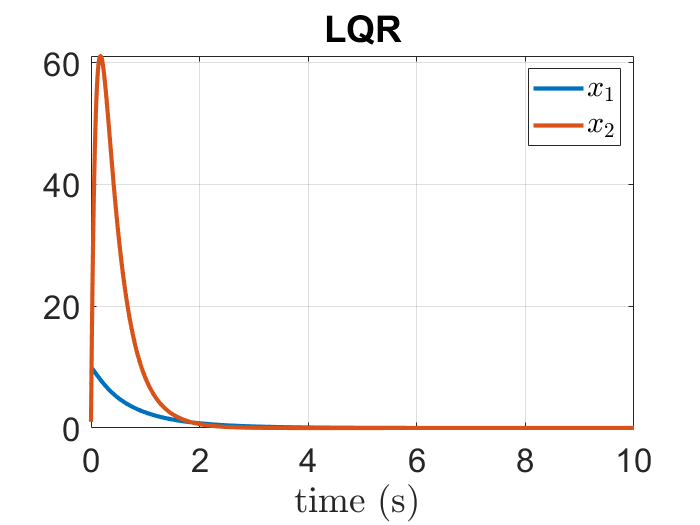

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

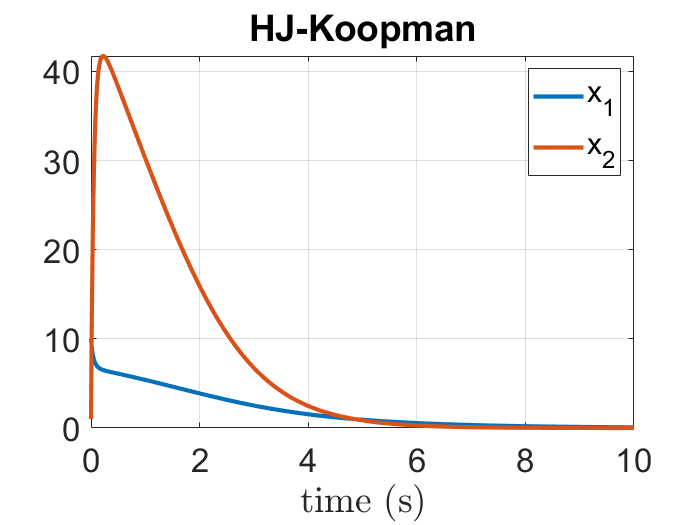

figure(2)
%subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');

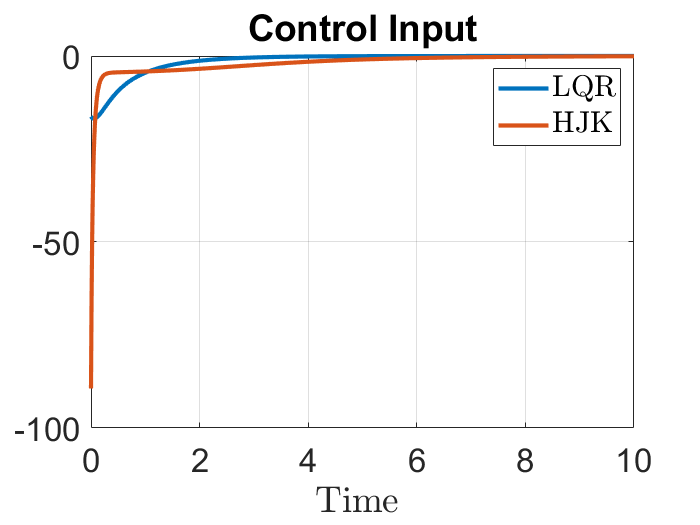

%set(LEG,'interpreter','latex')
figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

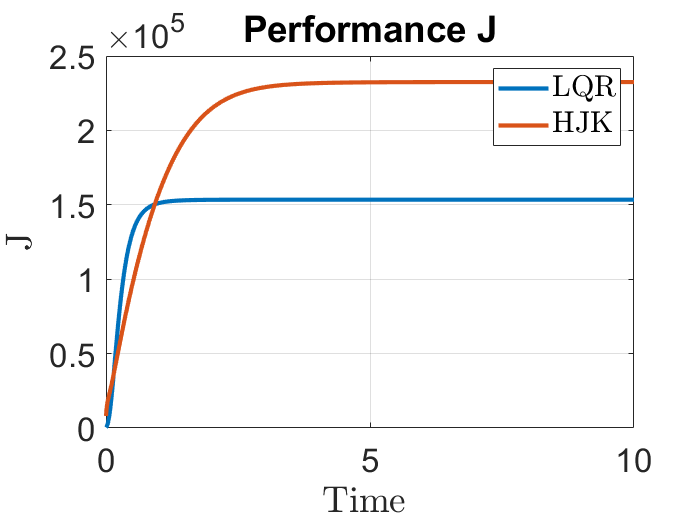

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Combined Plots

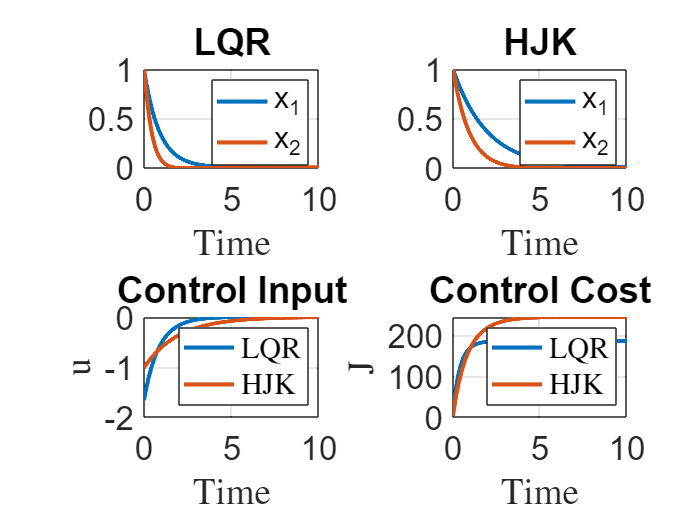

close all  
figure()
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');
%set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');
%set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 +U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    Psi = Psi';

end
Psi
end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end

DPsi = jacobian(Psi,x);

end

## Gaussian RBF basis

function [Psi, DPsi] = GaussianRBF_basis(C, dim, gamma)
%  [Psi, DPsi] = GaussianRBF_basis(deg, dim) returns a gaussian RBF function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   Centers = matrix of center points (size = (dim of x, K))
%   dim = number of states

x=sym('x',[dim,1]);
assume(x,'real')

Psi = [];
G = [];

for i=1:size(C,2)
    g = exp(-gamma*(norm(x-C(:,i)).^2));
    G = [G; g];
end

Psi = G
DPsi = jacobian(Psi,x);

end